M = 4; %QPSK

symbols = [0 1 2 3]; %Symbols
complexSymbols = [exp(1i*pi/4) exp(1i*3*pi/4) exp(1i*5*pi/4) exp(1i*7*pi/4)]; %Complex symbols

nSymbols = 1000000;
nBits = 2*nSymbols;

SNRdB = 0:1:10;
SNR = 10.^(SNRdB/10);
noiseAmp = 1./SNR;

ThBER = 0.5*erfc(sqrt(SNR));

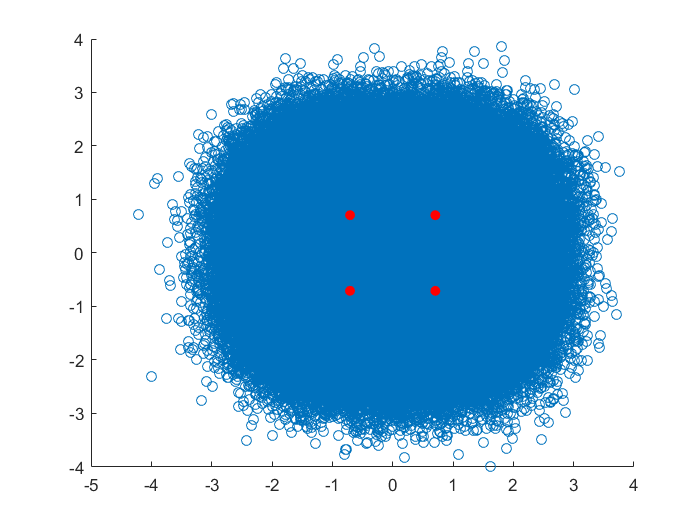

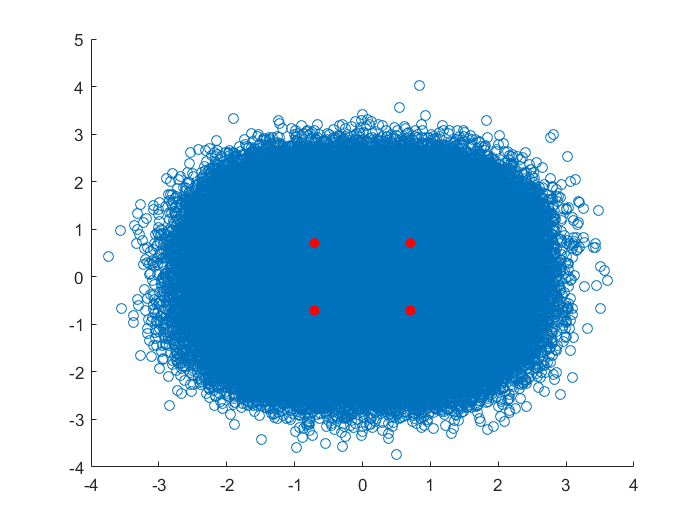

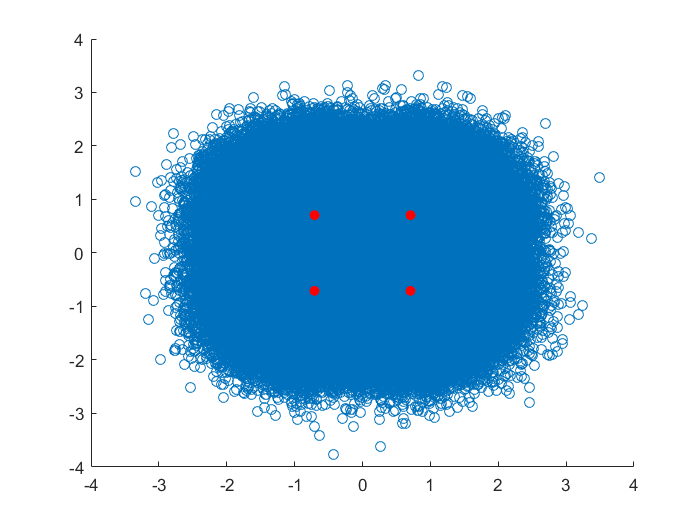

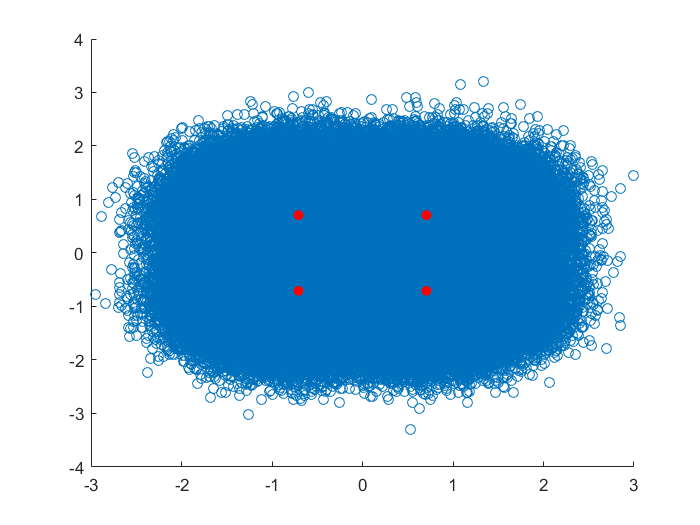

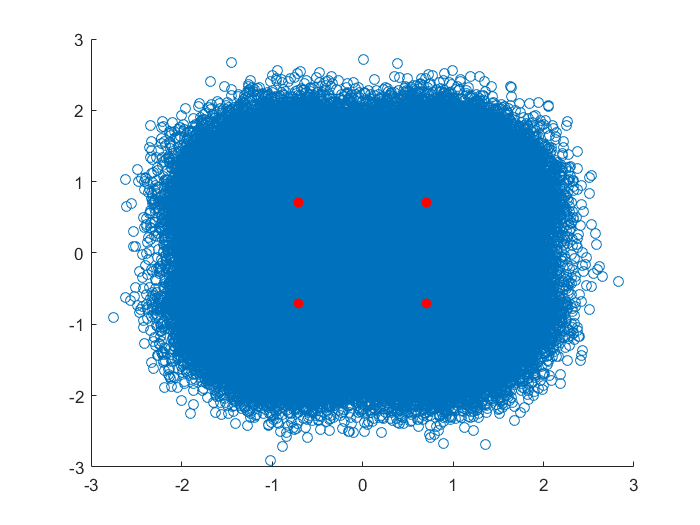

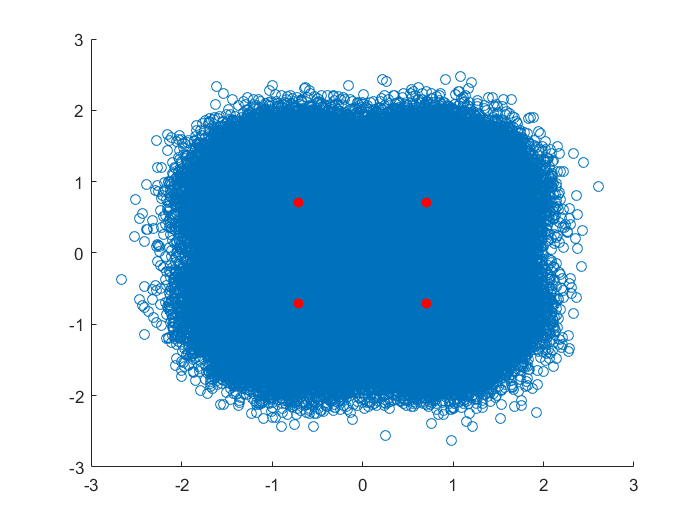

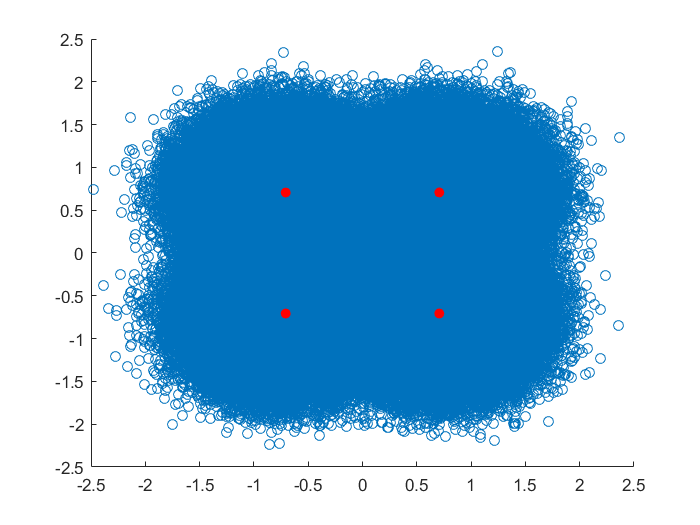

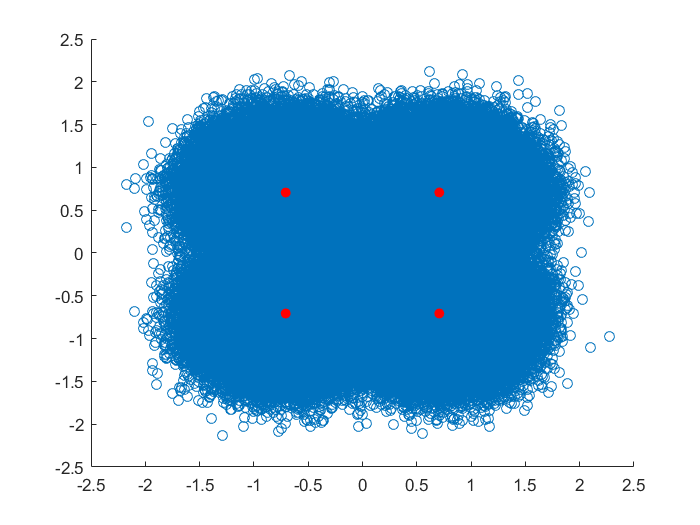

PracBER = zeros(1, length(SNRdB));

symbolMsgSig = zeros(1, nSymbols);
binMsgSig = zeros(1, nBits);
complexMsgSig = zeros(1, nSymbols);
channelComplexSig = zeros(1, nSymbols);
demodSymbolSig = zeros(1, nSymbols);
demodBinSig = zeros(1, nBits);

for SNRindex = 1:length(SNRdB)
    
    for index = 1:nSymbols
        symbolMsgSig(index) = symbols(randi(M));
    end
    
    for index = 1:nSymbols
        if symbolMsgSig(index) == 0
            binMsgSig(2*index-1) = 0;
            binMsgSig(2*index) = 0;
            complexMsgSig(index) = exp(1i*pi/4);
        elseif symbolMsgSig(index) == 1
            binMsgSig(2*index-1) = 0;
            binMsgSig(2*index) = 1;
            complexMsgSig(index) = exp(1i*3*pi/4);
        elseif symbolMsgSig(index) == 2
            binMsgSig(2*index-1) = 1;
            binMsgSig(2*index) = 0;
            complexMsgSig(index) = exp(1i*5*pi/4);
        else
            binMsgSig(2*index-1) = 1;
            binMsgSig(2*index) = 1;
            complexMsgSig(index) = exp(1i*7*pi/4);
        end
    end
    
    complexAWGNSig = transpose(sqrt(noiseAmp(SNRindex)/2)*(randn(nSymbols, 1) + 1i*randn(nSymbols, 1)));
    channelComplexSig = complexMsgSig + complexAWGNSig;
    
    for index = 1:nSymbols
        distVal = abs(complexSymbols - channelComplexSig(index));
        minDist = min(distVal);
        demodSymbolSig(index) = symbols(distVal == minDist);
    end
    
    PracBER(SNRindex) = sum(symbolMsgSig ~= demodSymbolSig)/nSymbols;
    
    figure(SNRindex);
    scatter(real(channelComplexSig), imag(channelComplexSig));
    hold on;
    scatter(real(complexSymbols), imag(complexSymbols), 'red', "filled");
    hold off;
end

PracBER

PracBER =     0.2922    0.2441    0.1973    0.1512    0.1097    0.0735    0.0456    0.0250    0.0119    0.0048    0.0016


ThBER

ThBER =     0.0786    0.0563    0.0375    0.0229    0.0125    0.0060    0.0024    0.0008    0.0002    0.0000    0.0000


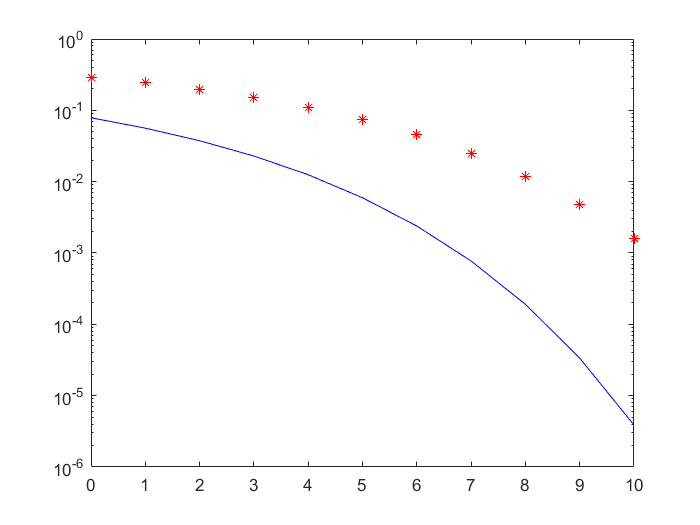

figure(SNRindex+1);
semilogy(SNRdB, PracBER, '*r');
hold on;
semilogy(SNRdB, ThBER, 'blue');
hold off;